clear all
syms P1 P2 v1 v2 rho D1 D2;

DP=P2-P1;

S1=(D1/2)^2*pi;
S2=(D2/2)^2*pi;
eqn1=S1*v1*rho==S2*v2*rho;
eqn2=P1+0.5*rho*v1^2==P2+0.5*rho*v2^2;
v2_=solve(eqn1,v2)

$$v2\_ = \frac{{D_{1}}^{2}\,v_{1}}{{D_{2}}^{2}}$$

eqn2=subs(eqn2,v2,v2_)

$$eqn2 = \frac{\rho \,{v_{1}}^{2}}{2}+P_{1}=P_{2}+\frac{{D_{1}}^{4}\,\rho \,{v_{1}}^{2}}{2\,{D_{2}}^{4}}$$

v1_=solve(eqn2,v1);
v1_=v1_(1)

$$v1\_ = \frac{\sqrt{2}\,{D_{2}}^{2}\,\sqrt{\rho \,\left(D_{1}-D_{2}\right)\,\left(P_{1}-P_{2}\right)\,\left({D_{1}}^{2}+{D_{2}}^{2}\right)\,\left(D_{1}+D_{2}\right)}}{{D_{1}}^{4}\,\rho -{D_{2}}^{4}\,\rho }$$

simplify(v1_)

$$ans = \frac{\sqrt{2}\,{D_{2}}^{2}\,\left(P_{1}-P_{2}\right)}{\sqrt{\rho \,\left(D_{1}-D_{2}\right)\,\left(P_{1}-P_{2}\right)\,\left({D_{1}}^{2}+{D_{2}}^{2}\right)\,\left(D_{1}+D_{2}\right)}}$$

## plot

syms DP
rho=997;%kg/m^3
D1=20e-3;
D2=10e-3;
S1=(D1/2)^2*pi;
S2=(D2/2)^2*pi;
eqn1=S1*v1*rho==S2*v2*rho;
eqn2=P1+0.5*rho*v1^2==P2+0.5*rho*v2^2;
v2_=solve(eqn1,v2)

$$v2\_ = 4\,v_{1}$$

eqn2=subs(eqn2,v2,v2_)

$$eqn2 = \frac{997\,{v_{1}}^{2}}{2}+P_{1}=7976\,{v_{1}}^{2}+P_{2}$$

v1_=solve(eqn2,v1);
v1_=v1_(1)

$$v1\_ = -\frac{\sqrt{2}\,\sqrt{14955}\,\sqrt{P_{1}-P_{2}}}{14955}$$

simplify(v1_)

$$ans = -\frac{\sqrt{29910}\,\sqrt{P_{1}-P_{2}}}{14955}$$

V1=subs(v1_,P2-P1,DP)

$$V1 = -\frac{\sqrt{2}\,\sqrt{14955}\,\sqrt{-\mathrm{DP}}}{14955}$$

DP_=solve(v1==V1,DP)

$$DP\_ = -\frac{14955\,{v_{1}}^{2}}{2}$$

v_ = 0:0.1:3;

DP_calc = subs(DP_,v1,v_)

$$DP\_calc = \left(\begin{array}{ccccccccccccccccccccccccccccccc} 0 & -\frac{2991}{40} & -\frac{2991}{10} & -\frac{26919}{40} & -\frac{5982}{5} & -\frac{14955}{8} & -\frac{26919}{10} & -\frac{146559}{40} & -\frac{23928}{5} & -\frac{242271}{40} & -\frac{14955}{2} & -\frac{361911}{40} & -\frac{53838}{5} & -\frac{505479}{40} & -\frac{146559}{10} & -\frac{134595}{8} & -\frac{95712}{5} & -\frac{864399}{40} & -\frac{242271}{10} & -\frac{1079751}{40} & -29910 & -\frac{1319031}{40} & -\frac{361911}{10} & -\frac{1582239}{40} & -\frac{215352}{5} & -\frac{373875}{8} & -\frac{505479}{10} & -\frac{2180439}{40} & -\frac{293118}{5} & -\frac{2515431}{40} & -\frac{134595}{2} \end{array}\right)$$

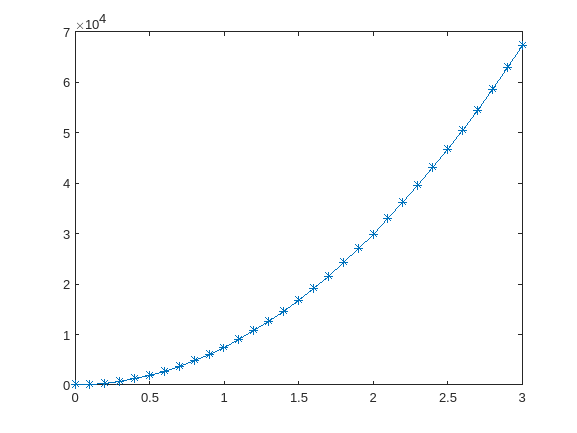

plot(v_,-DP_calc,'*-')


v_ = 0:0.1:3;

DP_calc = -double(subs(DP_,v1,v_))

DP_calc = 1.0e+04 *

         0    0.0075    0.0299    0.0673    0.1196    0.1869    0.2692    0.3664    0.4786    0.6057    0.7478    0.9048    1.0768    1.2637    1.4656    1.6824    1.9142    2.1610    2.4227    2.6994    2.9910    3.2976    3.6191    3.9556    4.3070    4.6734    5.0548    5.4511    5.8624    6.2886    6.7298


plot(v_,DP_calc,'*-')

## regressione

[P,G]=fit(DP_calc',v_','poly1')

'fit' requires one of the following:
  Curve Fitting Toolbox
  Predictive Maintenance Toolbox
  SimBiology
  Statistics and Machine Learning Toolbox
  Model-Based Calibration Toolbox

V_est=DP_calc*P.p1+P.p2
Rq=1-norm(v_-V_est)^2/norm(v_-mean(V_est))^2


[P_end,G]=fit([DP_calc(1) DP_calc(end)]',[v_(1) v_(end)]','poly1')
V_end=DP_calc*P_end.p1+P_end.p2
Rq=1-norm(v_-V_end)^2/norm(v_-mean(V_end))^2

## Scelta sensore

ris=5e-4;%m/s
V=0:ris:10;
DP=-double(subs(DP_,v1,V))

DP = 1.0e+05 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


ris=min(diff(DP))

ris = 0.0019

Pmax=max(DP)

Pmax = 747750

# ESERCIZIO 2

clear all
syms Rz PT100 Vout Rg
PT100_20=107.79;
PT100_150=157.31;
Rf=10;
Iref=200e-6

Iref = 2.0000e-04

G=5+200e3/Rg

$$G = \frac{200000}{\mathrm{Rg}}+5$$

## Punto 1

Vout=(Iref*(PT100)-Iref*(Rz))*G;
Vout_0=subs(Vout,PT100,PT100_20)==0

$$Vout\_0 = -\left(\frac{\mathrm{Rz}}{5000}-\frac{10779}{500000}\right)\,\left(\frac{200000}{\mathrm{Rg}}+5\right)=0$$

Vout_5=subs(Vout,PT100,PT100_150)==5

$$Vout\_5 = -\left(\frac{\mathrm{Rz}}{5000}-\frac{15731}{500000}\right)\,\left(\frac{200000}{\mathrm{Rg}}+5\right)=5$$

sol=solve([Vout_5;Vout_0]);

## Punto 2

Rg_id=double(sol.Rg)

Rg_id = 400.1228

Rz_id=double(sol.Rz)

Rz_id = 107.7900

Vout_id=subs(Vout,[Rg Rz],[Rg_id Rz_id])

$$Vout\_id = \frac{710726476802895881\,{\mathrm{PT}}_{100}}{7039035026255881000}-\frac{7660920693458414701299}{703903502625588100000}$$

PT100_=[107.79 108.18 108.57 108.96 109.35 109.73 110.12 110.51 110.90 111.28 ...
    111.67 112.06 112.45 112.83 113.22 113.61 113.99 114.38 114.77 115.15 ...
    115.54 115.93 116.31 116.70 117.08 117.47 117.85 118.24 118.62 119.01 ...
    119.40 119.78 120.16 120.55 120.93 121.32 121.70 122.09 122.47 122.86 ...
    123.24 123.62 124.01 124.39 124.77 125.16 125.54 125.92 126.31 126.69 ...
    127.07 127.45 127.84 128.22 128.60 128.98 129.37 129.75 130.13 130.51 ...
    130.89 131.27 131.66 132.04 132.42 132.80 133.18 133.56 133.94 134.32 ...
    134.70 135.08 135.46 135.84 136.22 136.60 136.98 137.36 137.74 138.12 ...
    138.50 138.88 139.26 139.64 140.02 140.39 140.77 141.15 141.53 141.91 ...
    142.29 142.66 143.04 143.42 143.80 144.17 144.55 144.93 145.31 145.68 ...
    146.06 146.44 146.81 147.19 147.57 147.94 148.32 148.70 149.07 149.45 ...
    149.82 150.20 150.57 150.95 151.33 151.70 152.08 152.45 152.83 153.20 ...
    153.58 153.95 154.32 154.70 155.07 155.45 155.82 156.19 156.57 156.94 ...
    157.31]

PT100_ =   107.7900  108.1800  108.5700  108.9600  109.3500  109.7300  110.1200  110.5100  110.9000  111.2800  111.6700  112.0600  112.4500  112.8300  113.2200  113.6100  113.9900  114.3800  114.7700  115.1500  115.5400  115.9300  116.3100  116.7000  117.0800  117.4700  117.8500  118.2400  118.6200  119.0100  119.4000  119.7800  120.1600  120.5500  120.9300  121.3200  121.7000  122.0900  122.4700  122.8600  123.2400  123.6200  124.0100  124.3900  124.7700  125.1600  125.5400  125.9200  126.3100  126.6900


## Punto 3

Vout_id=double(subs(Vout_id,PT100,PT100_))

Vout_id =          0    0.0394    0.0788    0.1181    0.1575    0.1959    0.2353    0.2746    0.3140    0.3524    0.3918    0.4311    0.4705    0.5089    0.5483    0.5876    0.6260    0.6654    0.7048    0.7431    0.7825    0.8219    0.8603    0.8996    0.9380    0.9774    1.0158    1.0551    1.0935    1.1329    1.1723    1.2106    1.2490    1.2884    1.3267    1.3661    1.4045    1.4439    1.4822    1.5216    1.5600    1.5983    1.6377    1.6761    1.7145    1.7538    1.7922    1.8306    1.8700    1.9083


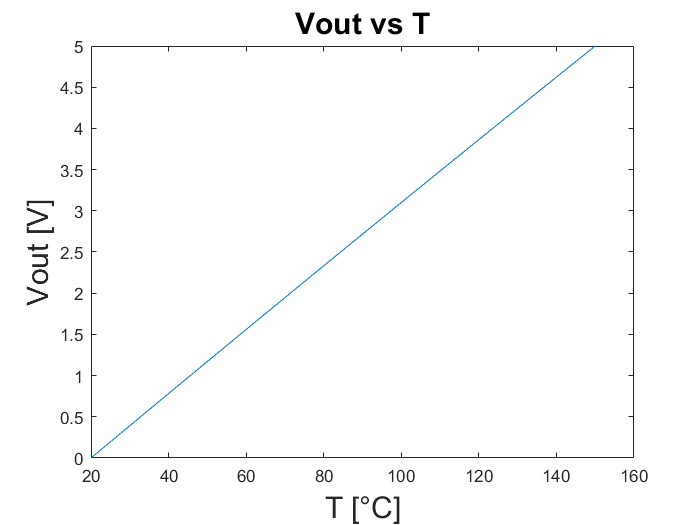

T_=[20:150];
plot(T_,Vout_id)
title("Vout vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vout [V]","FontSize",18)

 [P_BSFT,G_BSFT]=fit(Vout_id',T_','poly1')

P_BSFT =      Linear model Poly1:
     P_BSFT(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =          26  (25.97, 26.02)
       p2 =       19.57  (19.5, 19.64)

G_BSFT = struct with fields:
           sse: 4.9649
       rsquare: 1.0000
           dfe: 129
    adjrsquare: 1.0000
          rmse: 0.1962


 T_est_BFST=Vout_id*P_BSFT.p1+P_BSFT.p2;
 err_lin_BSFT=max(abs(T_-T_est_BFST))/T_(end)*100

err_lin_BSFT = 0.2928

## Valori reali

Rz_real=110.8

Rz_real = 110.8000

Rg_real=409

Rg_real = 409

Vout_real=subs(Vout,[Rg Rz],[Rg_real Rz_real])

$$Vout\_real = \frac{40409\,{\mathrm{PT}}_{100}}{409000}-\frac{11193293}{1022500}$$

PT100min=108.8

PT100min = 108.8000

PT100max=160.3

PT100max = 160.3000

Vout_real_=double(subs(Vout_real,PT100,PT100min))

Vout_real_ = -0.1976

Vout_real_=double(subs(Vout_real,PT100,PT100max))

Vout_real_ = 4.8906

Vout_real=double(subs(Vout_real,PT100,PT100_))

Vout_real =    -0.2974   -0.2589   -0.2203   -0.1818   -0.1433   -0.1057   -0.0672   -0.0287    0.0099    0.0474    0.0860    0.1245    0.1630    0.2006    0.2391    0.2776    0.3152    0.3537    0.3922    0.4298    0.4683    0.5068    0.5444    0.5829    0.6205    0.6590    0.6965    0.7351    0.7726    0.8111    0.8497    0.8872    0.9248    0.9633    1.0008    1.0394    1.0769    1.1154    1.1530    1.1915    1.2291    1.2666    1.3051    1.3427    1.3802    1.4188    1.4563    1.4938    1.5324    1.5699


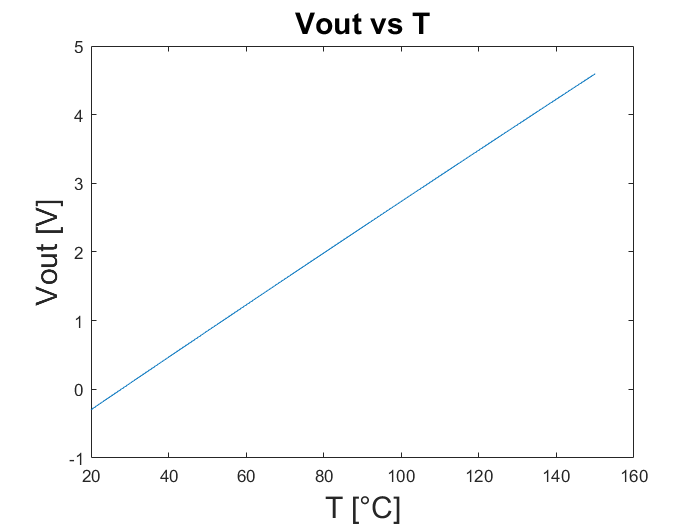

T_=[20:150];
plot(T_,Vout_real)
title("Vout vs T","FontSize",18)
xlabel("T [°C]","FontSize",18)
ylabel("Vout [V]","FontSize",18)

[P_BSFT,G_BSFT]=fit(Vout_real',T_','poly1')

P_BSFT =      Linear model Poly1:
     P_BSFT(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       26.57  (26.55, 26.59)
       p2 =       27.47  (27.41, 27.53)

G_BSFT = struct with fields:
           sse: 4.9649
       rsquare: 1.0000
           dfe: 129
    adjrsquare: 1.0000
          rmse: 0.1962


T_est_BFST=Vout_real*P_BSFT.p1+P_BSFT.p2;
err_lin_BSFT=max(abs(T_-T_est_BFST))/T_(end)*100

err_lin_BSFT = 0.2928

T_reale=[109.5;
        0]

T_reale =   109.5000
         0


Vp=0.023

Vp = 0.0230

Vm=0.022

Vm = 0.0220

rf=11

rf = 11